# Run Simulation

#### Set parameters

Specify the folder where the executables live

iwfm_bin = fullfile('..','..','..','IWFM','IWFM_2015_0_1045','iwfm-2015.0.1045_sourcecode','IWFM','IWFM-2015.0.1045','Bin');
nTimeSteps = 12;
SBE = [91 97]; % Stream Bottom Elevation 

#### Run preprocessor

The filepaths have been setup so that 

system([iwfm_bin filesep 'PreProcessor2015_D.exe Preprocessor' filesep 'Ex1_Preprocessor.in']);

        ╔══════════════════════════════════════════════════════╗ 
        ║             Integrated Water Flow Model              ║ 
        ║                       IWFM                           ║ 
        ║                Program: Pre-Processor                ║ 
        Ã──────────────────────────────────────────────────────Â 
        ║                 Version: 2015.0.1045                 ║ 
        ║               Copyright (C) 2005-2021                ║ 
        ║  State of California, Department of Water Resources  ║ 
        Ã──────────────────────────────────────────────────────Â 
        ║ This program is free software; you can redistribute  ║ 
        ║ it and/or modify it under the terms of the GNU       ║ 
        ║ General Public License as published by the Free      ║ 
        ║ Software Foundation; either version 2 of the         ║ 
        ║ License or (at your option) any later version.       ║ 
        ║                                                      ║ 
        ║ 

#### Run Simulation

system([iwfm_bin filesep 'Simulation2015_D.exe Simulation' filesep 'Ex1_Simulation.in']);

        ╔══════════════════════════════════════════════════════╗ 
        ║             Integrated Water Flow Model              ║ 
        ║                       IWFM                           ║ 
        ║                 Program: Simulation                  ║ 
        Ã──────────────────────────────────────────────────────Â 
        ║                 Version: 2015.0.1045                 ║ 
        ║               Copyright (C) 2005-2021                ║ 
        ║  State of California, Department of Water Resources  ║ 
        Ã──────────────────────────────────────────────────────Â 
        ║ This program is free software; you can redistribute  ║ 
        ║ it and/or modify it under the terms of the GNU       ║ 
        ║ General Public License as published by the Free      ║ 
        ║ Software Foundation; either version 2 of the         ║ 
        ║ License or (at your option) any later version.       ║ 
        ║                                                      ║ 
        ║ 

#### Post process results

This snippet requires functions that can be obtained from the [gwtools](https://github.com/UCD-GW-Nitrate/gwtools) repository

XY = readIWFM_Nodes(fullfile('Preprocessor','Ex1_Nodes.dat'));
H = readIWFM_headalloutput(fullfile('Results','Ex1_GW_HeadAll.out'), false);

Plot the head of the last step against the stream bottom

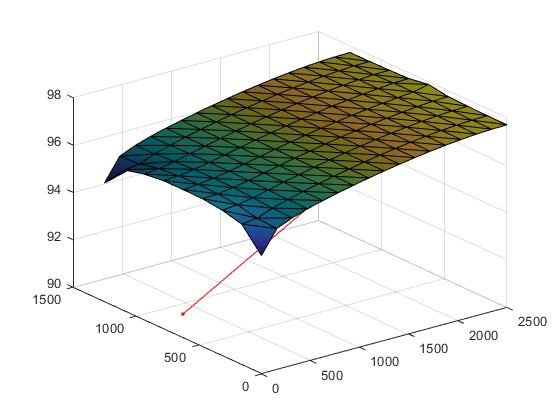

clf
tr = delaunay(XY(:,1), XY(:,2));
for ii = length(H)
    trisurf(tr,XY(:,1), XY(:,2), H{ii,2}(:,1),'FaceColor','interp','FaceLighting','phong')
    camlight right
    %drawnow
    %pause(0.5)
    %M(ii) = getframe;
    %im{ii} = frame2im(M(ii));
end
hold on
plot3([0,2500],[625 625],SBE,'.-r')

Read the Stream Budget

strm_bud = h5info(fullfile('Results','Ex1_Stream_Budget.hdf'));
tmp = h5read(strm_bud.Filename,[strm_bud.Name strm_bud.Datasets(1).Name]);

Stream budget on nodes

strm_node_bud = h5info(fullfile('Results','Ex1_Stream_Node_Budget.hdf'));
Stream_col_names = strm_node_bud.Groups.Attributes(11).Value(2:end);
strm_nodesGW = zeros(length(strm_node_bud.Datasets), nTimeSteps);
strm_nodesUpIn = zeros(length(strm_node_bud.Datasets), nTimeSteps);
strm_nodesDwOut = zeros(length(strm_node_bud.Datasets), nTimeSteps);
for ii = 1:length(strm_node_bud.Datasets)
    id = textscan(strm_node_bud.Datasets(ii).Name,'NODE%s');
    id = str2double(id{1,1}{1,1});
    ttt = h5read(strm_node_bud.Filename,[strm_node_bud.Name strm_node_bud.Datasets(ii).Name]);
    strm_nodesGW(id,:) = ttt(7, :);
    strm_nodesUpIn(id,:) = ttt(1, :);
    strm_nodesDwOut(id,:) = ttt(2, :);
end